%%Plan Path for Manipulator Robot Using RRT
clear
clc
robot = loadrobot("abbYuMi","DataFormat","column","Gravity",[0 0 -9.81]);
env = {collisionBox(0.2, 0.2, 0.02) collisionSphere(0.15)};
env{1}.Pose = trvec2tform([0.1 0.2 0.5]);
env{2}.Pose = trvec2tform([-0.5 0.2 0.5]);
load abbYumiSaveTrajectoryWaypts.mat
show(robot)

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


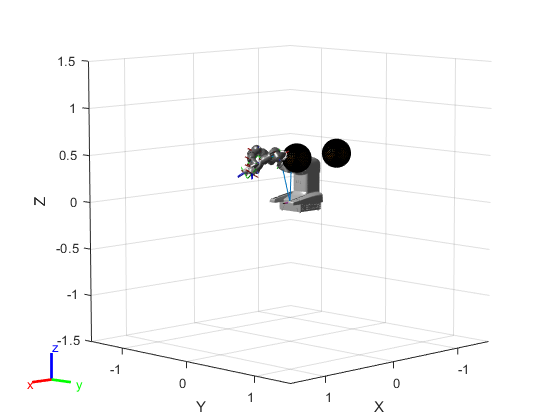

hold on
show(env{1})
show(env{2})

collisionArrayFromMesh = cell (robot.NumBodies+1,2);
collisionMeshPath = fullfile(matlabroot, 'toolbox', 'robotics', ...
        'robotexamples', 'robotmanip', 'data', 'yumi_description', ...
        'meshes', 'abbYumi', 'collision');
yumiCollision = importrobot('abbYuMi.urdf','MeshPath', collisionMeshPath);
yumiCollision.DataFormat = 'column';
robotBodies = [{yumiCollision.Base} yumiCollision.Bodies];
for i = 1:numel(robotBodies)
    if ~isempty(robotBodies{i}.Visuals)
        % Assumes the first Visuals element is the correct one.
        visualDetails = robotBodies{i}.Visuals{1};
        
        % Extract the part of the visual that actually specifies the STL name
        visualParts = strsplit(visualDetails, ':');
        stlFileName = visualParts{2};
        
        % Read the STL file
        stlData = stlread(fullfile(collisionMeshPath, stlFileName));
        
        % Create a collisionMesh object from the vertices
        collisionArrayFromMesh{i,1} = collisionMesh(stlData.Points);
        
        % Transform is always identity
        collisionArrayFromMesh{i,2} = eye(4);
    end
end